# Debugging tapas_compute_statistics.m on our simulated data

When using `tapas_rdcm_estimate.m` on our data it crashed if ln 176 where `tapas_rdcm_compute_statistics.m` is called on DCM, output, options. 

While we can get results for model inversion without this we don't get the built-in model fit information.

So what goes wrong?

Generate some data

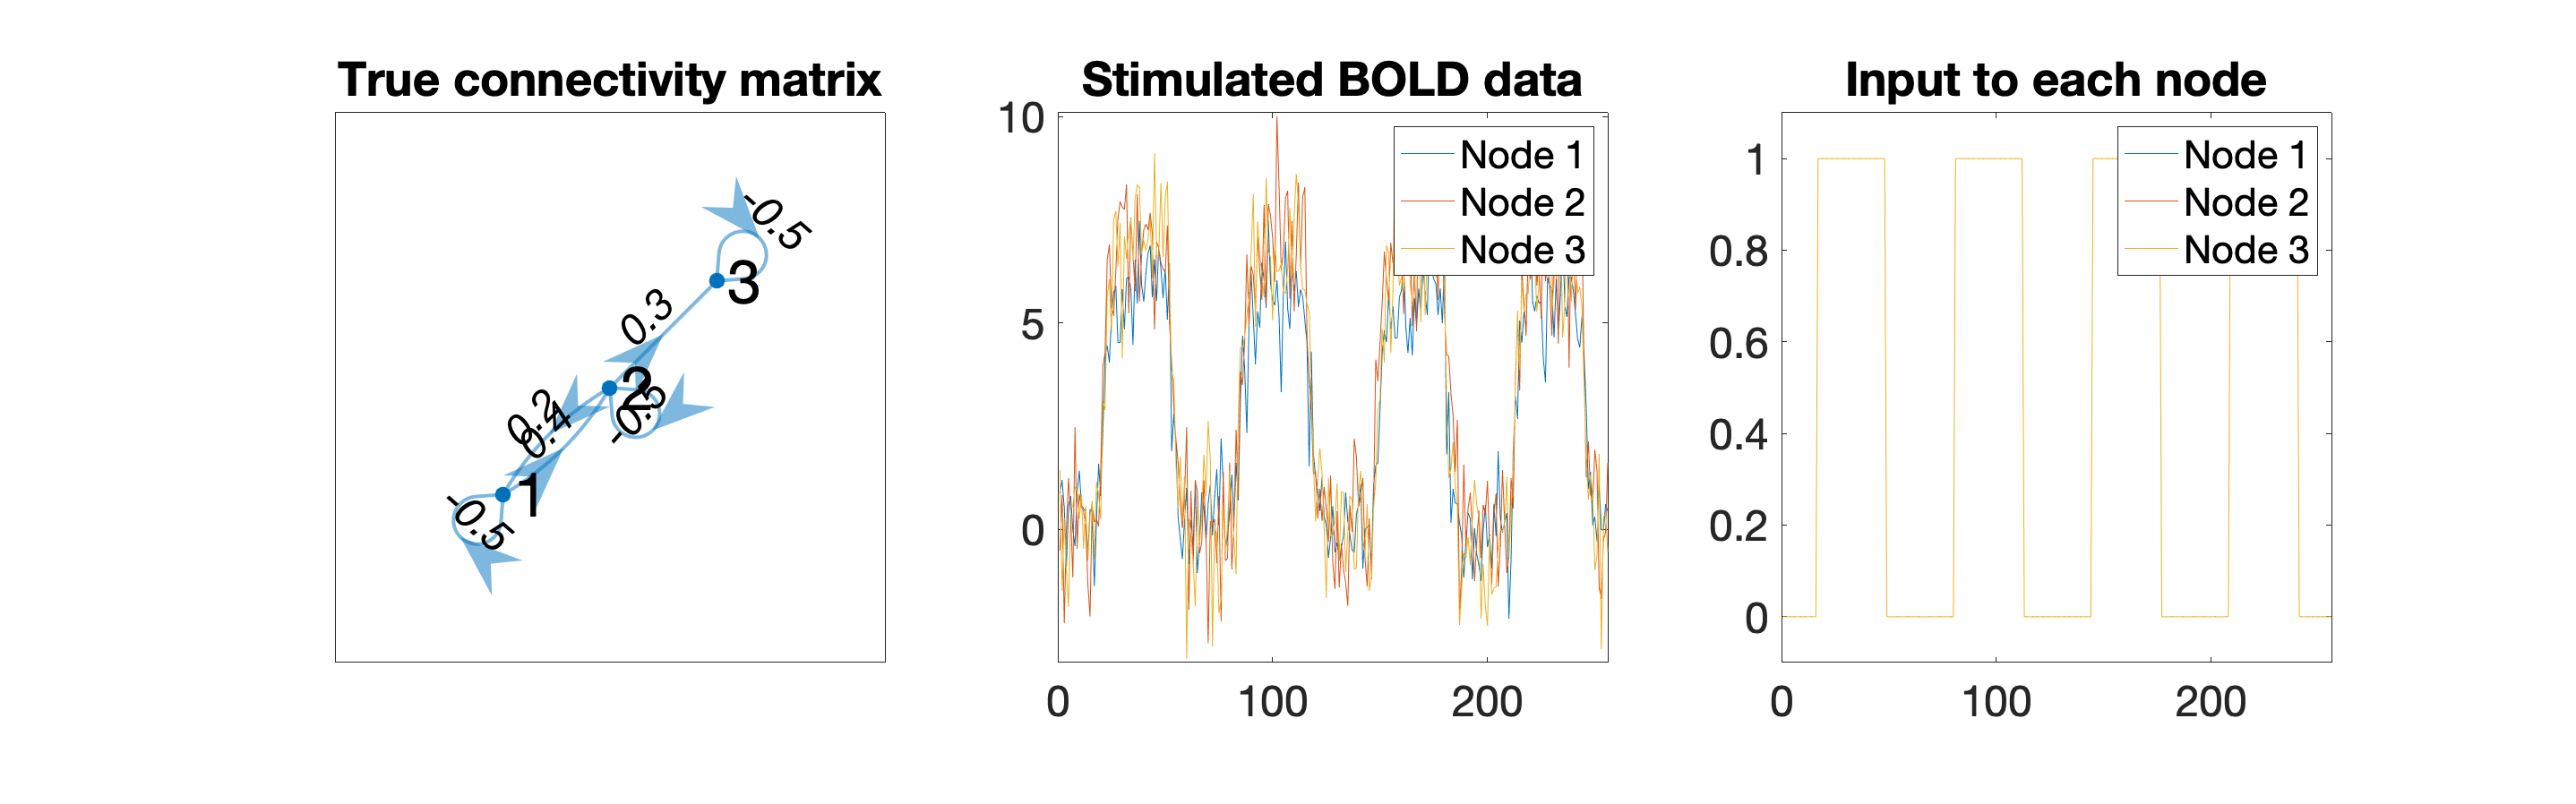

stim_options = get_default_stim_options();
on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = 1/8;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [1,2,3];
stim_options.c = eye(stim_options.n);
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

[DCM, options] = make_task_fmri(stim_options);
plot_sim_data(DCM)

Step through code in `tapas_rdcm_estimate.m` up until the line of crash

rngSeed = rng();
type = 's';
methods = 2;

% check for endogenous DCMs, with no exogenous driving effects
if ( ~isfield(DCM,'c') || isempty(DCM.c) || ~isfield(DCM,'U') || isempty(DCM.U.u) || strcmp(DCM.U.name{1},'null') )
    
    % specify empty driving input
    DCM.U.u     = zeros(size(DCM.Y.y,1)*16, 1);
    DCM.U.name  = {'null'};
    DCM.U.dt    = DCM.Y.dt/16;
    
    % specify effective connectivity matrices
    DCM.b = zeros(DCM.n, DCM.n, size(DCM.U.u,2));
    DCM.c = zeros(DCM.n, size(DCM.U.u,2));
    DCM.d = zeros(DCM.n, DCM.n, 0);
    
end


% create the options file
options = tapas_rdcm_set_options(DCM, options, type);


% create the regressors
[X, Y, DCM, args] = tapas_rdcm_create_regressors(DCM, options);



% evaluate results (model inversion)
if ( methods == 1 )
    
    % rDCM (original)
    output = tapas_rdcm_ridge(DCM, X, Y, args ); 

elseif ( methods == 2 )
    
    % specify the default grid for optimizing sparsity hyperparameter p0
    if ( ~isfield(options,'p0_all') )
        options.p0_all = 0.05:0.05:0.95;
    end
    
    % result array for all p0
    output_all  = cell(1,length(options.p0_all));
    F_all       = NaN(1,length(options.p0_all));
    
    % for command output
    reverseStr = '';
    
    % prune driving inputs or not
    if ( isfield(options,'restrictInputs') ), args.restrictInputs = options.restrictInputs; end
    
    
    % iterate over p0 values
    for p0_counter = 1:length(options.p0_all)
        
        % specify p0
        args.p0_temp = options.p0_all(p0_counter);
        
        % specify the number of permutations (per brain region)
        if ( isfield(options,'iter') ), args.iter = options.iter; end
        
        % specify whether to inform p0 (e.g., by anatomical information)
        if ( isfield(options,'p0_inform') ), args.p0_inform = options.p0_inform; end
        
        % output progress of regions
        if ( length(options.p0_all) ~= 1 ), args.verbose = 0; else, args.verbose = 1; end
        
        % output progress
        if ( ~isfield(DCM,'M') || ~isfield(DCM.M,'noprint') || ~DCM.M.noprint )
            msg = sprintf('Processing p0: %d/%d', p0_counter, length(options.p0_all));
            fprintf([reverseStr, msg]);
            reverseStr = repmat(sprintf('\b'), 1, length(msg));
        end
        
        % rDCM (with sparsity constraints)
        output_temp	= tapas_rdcm_sparse(DCM, X, Y, args);
        output_all{p0_counter} = output_temp{1};
        
        % get the negative free energy
        F_all(p0_counter) = output_all{p0_counter}.logF;
        
    end
    
    
    % find optimal hyperparameter settings (p0)
    [~, F_max_ind] = max(F_all);
    
    % asign results
    output = output_all{F_max_ind};
    
end

Processing p0: 19/19

`tapas_rdcm_compute_statistics.m > tapas_rdcm_compute_signals.m > tapas_rdcm_generate.m > tapas_dcm_euler_gen.m`

Problem is when 

calls

`tapas_rdcm_generate.m > tapas_dcm_euler_gen.m` isn't always broken. What do the parameters look like for a case when it works?

temp = load('tapas-master/rDCM/test/DCM_LargeScaleSmith_model1.mat');
working_DCM  = temp.DCM;


% specify the options for the rDCM analysis
working_options.SNR             = 3;
working_options.y_dt            = 0.5;
working_options.p0_all          = 0.15;  % single p0 value (for computational efficiency)
working_options.iter            = 100;
working_options.filter_str      = 5;
working_options.restrictInputs  = 1;

% run a simulation (synthetic) analysis
type = 's';

%% generate synthetic data

% generate synthetic data (for simulations)
working_DCM = tapas_rdcm_generate(working_DCM, working_options, working_options.SNR);